# **Impedance Model**

## I Second order model representation

If we consider that a simple mass $M$, damper $B$, spring $K$, system is to be able to model the impedance behaviour of the human arm along an axis $\overrightarrow{x}$, while interacting with an environment then, we can write:

$\left({\textrm{Ms}}^2 +\textrm{Bs}+K\right)X_e \left(s\right)=F_e \left(s\right)$,

with$X$ the endpoint position of the arm, and $F$ the force of the arm on the environment, both along $\overrightarrow{x}$.

clear all
syms Ms Bs Ks;
% impedance parameters
Mv = 0.5;
Bv = 10;
Kv = 200;

The state representation of the system is:

$\dot{\mathit{\mathbf{X}}} \left(t\right)=\textrm{AX}\left(t\right)+\textrm{Bu}\left(t\right)$,


$$y\left(t\right)=\textrm{CX}\left(t\right)$$


$\mathit{\mathbf{X}}\left(t\right)=\left\lbrack \begin{array}{c}
x_e \left(t\right)\\
\dot{x_e } \left(t\right)
\end{array}\right\rbrack$, $u\left(t\right)=f_e \left(t\right)$

A = [  0 ,   1 ;
     -Ks/Ms, -Bs/Ms]

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{\mathrm{Ks}}{\mathrm{Ms}} & -\frac{\mathrm{Bs}}{\mathrm{Ms}} \end{array}\right)$$

B = [0; 1/Ms]

$$B = \left(\begin{array}{c} 0\\ \frac{1}{\mathrm{Ms}} \end{array}\right)$$

C = [1, 0] % or C = [0, 1] if the velocity is considered as output

C =      1     0


% Simulated state space system representation
Ass = double(subs(A, [Ks, Bs, Ms], [Kv, Bv, Mv]));
Bss = double(subs(B, [Ks, Bs, Ms], [Kv, Bv, Mv]));
Css = double(subs(C, [Ks, Bs, Ms], [Kv, Bv, Mv]));
KBM_ss = ss(Ass,Bss,Css,0);

## II Discretization

### II-a State system

Assuming that the discretization is made through a zero order hold, and a sampling period $T$:


$$\mathit{\mathbf{X}}\left\lbrack k+1\right\rbrack ={\mathit{\mathbf{A}}}_d \mathit{\mathbf{X}}\left\lbrack k\right\rbrack +{\mathit{\mathbf{B}}}_d \;u\left\lbrack k\right\rbrack$$



$${\mathit{\mathbf{A}}}_d =e^{\mathit{\mathbf{A}}\;T} ,$$



$${\mathit{\mathbf{B}}}_d =\left(\int_{\tau =0}^T e^{\mathit{\mathbf{A}}\tau \;} d\tau \;\right)\mathit{\mathbf{B}}={\mathit{\mathbf{A}}}^{-1} \left({\mathit{\mathbf{A}}}_d -\mathit{\mathbf{I}}\right)\mathit{\mathbf{B}},\exists \;{\mathit{\mathbf{A}}}^{-1}$$


dt = 1e-3; % 1ms
Ad = expm(A*dt) % ilaplace(inv(s*eye(2)-A),s,dt)

$$Ad = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{2}\,\sqrt{\sigma_{3}}-\mathrm{Bs}\,\sigma_{2}+\mathrm{Bs}\,\sigma_{1}+\sigma_{1}\,\sqrt{\sigma_{3}}}{2\,\sqrt{\sigma_{3}}} & -\frac{\sigma_{1}\,\sigma_{3}+{\mathrm{Bs}}^{2}\,\sigma_{2}-\sigma_{2}\,\sigma_{3}-{\mathrm{Bs}}^{2}\,\sigma_{1}}{4\,\mathrm{Ks}\,\sqrt{\sigma_{3}}}\\ \frac{\mathrm{Ks}\,\sigma_{2}-\mathrm{Ks}\,\sigma_{1}}{\sqrt{\sigma_{3}}} & \frac{\mathrm{Bs}\,\sigma_{2}+\sigma_{2}\,\sqrt{\sigma_{3}}-\mathrm{Bs}\,\sigma_{1}+\sigma_{1}\,\sqrt{\sigma_{3}}}{2\,\sqrt{\sigma_{3}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\mathrm{Bs}-\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}}\\ \sigma_{2}={\mathrm{e}}^{-\frac{\mathrm{Bs}+\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}}\\ \sigma_{3}={\mathrm{Bs}}^{2}-4\,\mathrm{Ks}\,\mathrm{Ms} \end{array}$$

Bd = A\(Ad - eye(2))*B % if A is not a singular matrix

$$Bd = \begin{array}{l} \left(\begin{array}{c} -\frac{{\mathrm{e}}^{-\sigma_{2}}\,{\mathrm{e}}^{-\sigma_{1}}\,\left({\mathrm{Bs}}^{3}\,{\mathrm{e}}^{\sigma_{2}}-{\mathrm{Bs}}^{3}\,{\mathrm{e}}^{\sigma_{1}}-\mathrm{Bs}\,{\mathrm{e}}^{\sigma_{2}}\,\sigma_{3}+\mathrm{Bs}\,{\mathrm{e}}^{\sigma_{1}}\,\sigma_{3}+2\,\mathrm{Bs}\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{1}}+2\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{1}}\,\sqrt{\sigma_{3}}-2\,\mathrm{Bs}\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{2}}+2\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{2}}\,\sqrt{\sigma_{3}}-4\,\mathrm{Ks}\,\mathrm{Ms}\,{\mathrm{e}}^{\sigma_{2}}\,{\mathrm{e}}^{\sigma_{1}}\,\sqrt{\sigma_{3}}\right)}{4\,{\mathrm{Ks}}^{2}\,\mathrm{Ms}\,\sqrt{\sigma_{3}}}\\ \frac{{\mathrm{e}}^{-\sigma_{2}}\,{\mathrm{e}}^{-\sigma_{1}}\,\left({\mathrm{e}}^{\sigma_{1}}\,\sigma_{3}+{\mathrm{Bs}}^{2}\,{\mathrm{e}}^{\sigma_{2}}-{\mathrm{e}}^{\sigma_{2}}\,\sigma_{3}-{\mathrm{Bs}}^{2}\,{\mathrm{e}}^{\sigma_{1}}\right)}{4\,\mathrm{Ks}\,\mathrm{Ms}\,\sqrt{\sigma_{3}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Bs}-\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}\\ \sigma_{2}=\frac{\mathrm{Bs}+\sqrt{\sigma_{3}}}{2000\,\mathrm{Ms}}\\ \sigma_{3}={\mathrm{Bs}}^{2}-4\,\mathrm{Ks}\,\mathrm{Ms} \end{array}$$

Cd = C;
% Simulated discrete state space system representation
Adss = double(subs(Ad, [Ks, Bs, Ms], [Kv, Bv, Mv]));
Bdss = real(double(subs(Bd, [Ks, Bs, Ms], [Kv, Bv, Mv])));
KBM_dss = ss(Adss,Bdss,Cd,0,dt);

The eigenvalues $\lambda$ of the eigenvector $v$ of the discretized state system can be evaluated using either $\mathit{\mathbf{A}}\;\textrm{or}\;{\mathit{\mathbf{A}}}_d$:

  
$$\textrm{det}\left(A-\lambda I\right)v=0$$


eigAd = eig(Ad);
eigAd2 = exp(eig(A)*dt);
if (eigAd - eigAd2) ~= 0
    warning('The two eigen values vectors should be the same...')
end

However we can simply note that the characteristic polynomial of $A$ is already known in this case, and therefore, the eigenvalues can be found by solving the roots of this polynomial:


$${M\lambda }^2 +B\lambda +K=0\Leftrightarrow \lambda_{A_{1,2} } =\frac{-B\pm {\left(B^2 -4\textrm{MK}\right)}^{\frac{1}{2}} }{2M}$$


Then we can simply deduced the eigenvalues of $A_d$: ${\lambda^i }_{A_d } =e^{{\lambda^i }_A T}$


$$\lambda_{{\textrm{Ad}}_{1,2} } =e^{\frac{-B\pm {\left(B^2 -4\textrm{MK}\right)}^{\frac{1}{2}} }{2M}\;T}$$


### II-b Transfer function form

We can now express the transfer function that relates the input force $f_e$ to the output position $x_e$ using $H\left(z\right)={\mathit{\mathbf{C}}}_d \;\left(z\;\mathit{\mathbf{I}}-{\mathit{\mathbf{A}}}_d {\left.\right)}^{-1} {\;\mathit{\mathbf{B}}}_d \right.$, with $\mathit{\mathbf{I}}$ the identity matrix.

z = sym('z');
Hd = simplify(Cd*(z*eye(2) - Ad)^(-1)*Bd);
[n,d] = numden(Hd);
n = collect(n,z)

$$n = \begin{array}{l} \left(2\,{\mathrm{e}}^{\frac{\mathrm{Bs}}{1000\,\mathrm{Ms}}}\,\sigma_{5}-\sigma_{4}-\sigma_{2}+\sigma_{1}-\sigma_{3}\right)\,z+\sigma_{2}-\sigma_{4}+2\,\sigma_{5}-\sigma_{1}-\sigma_{3}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Bs}\,{\mathrm{e}}^{\frac{\mathrm{Bs}-\sigma_{5}}{2000\,\mathrm{Ms}}}\\ \sigma_{2}=\mathrm{Bs}\,{\mathrm{e}}^{\frac{\mathrm{Bs}+\sigma_{5}}{2000\,\mathrm{Ms}}}\\ \sigma_{3}={\mathrm{e}}^{\frac{\mathrm{Bs}-\sigma_{5}}{2000\,\mathrm{Ms}}}\,\sigma_{5}\\ \sigma_{4}={\mathrm{e}}^{\frac{\mathrm{Bs}+\sigma_{5}}{2000\,\mathrm{Ms}}}\,\sigma_{5}\\ \sigma_{5}=\sqrt{{\mathrm{Bs}}^{2}-4\,\mathrm{Ks}\,\mathrm{Ms}} \end{array}$$

d = collect(d,z)

$$d = \begin{array}{l} \left(2\,\mathrm{Ks}\,{\mathrm{e}}^{\frac{\mathrm{Bs}}{1000\,\mathrm{Ms}}}\,\sigma_{1}\right)\,z^{2}+\left(-2\,\left(\mathrm{Ks}\,{\mathrm{e}}^{\frac{\mathrm{Bs}+\sigma_{1}}{2000\,\mathrm{Ms}}}+\mathrm{Ks}\,{\mathrm{e}}^{\frac{\mathrm{Bs}-\sigma_{1}}{2000\,\mathrm{Ms}}}\right)\,\sigma_{1}\right)\,z+2\,\mathrm{Ks}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\mathrm{Bs}}^{2}-4\,\mathrm{Ks}\,\mathrm{Ms}} \end{array}$$

b_coef = flip(coeffs(n,z)); % high order first
a_coef = flip(coeffs(d,z));

We know now that we have a transfer function of the form:


$$\frac{X_e \left(z\right)}{F_e \left(z\right)}{\;=\;H}_d \left(z\right)=K_H \frac{z+b_0 }{z^2 +a_1 z+a_0 }=\frac{{b_1 }^{\prime } \;z+{b_0 }^{\prime } }{{{a_2 }^{\prime } z}^2 +{a_1 }^{\prime } z+{a_0 }^{\prime } }$$


$K_H =\frac{{b_1 }^{\prime } }{{a_2 }^{\prime } }$, $b_0 =\frac{{b_0 }^{\prime } }{{b_1 }^{\prime } }$, $a_1 =\frac{{a_1 }^{\prime } }{{a_2 }^{\prime } }$, $a_0 =\frac{{a_0 }^{\prime } }{{a_2 }^{\prime } }$

Kh = b_coef(1)/a_coef(1);
b0 = b_coef(2)/b_coef(1);
a1 = a_coef(2)/a_coef(1);
a0 = a_coef(3)/a_coef(1);

Knowing the desired/tested impedance parameters, it is already possible to evaluate the expected coefficient:

a1v = double(subs(a1,[Ks,Bs,Ms],[Kv,Bv,Mv]))

a1v = -1.9798

a0v = double(subs(a0,[Bs,Ms],[Bv,Mv])) % do not depends on K

a0v = 0.9802

Khv = double(subs(Kh,[Ks,Bs,Ms],[Kv,Bv,Mv]))

Khv = 9.9333e-07

Khb0v = double(subs(Kh*b0,[Ks,Bs,Ms],[Kv,Bv,Mv]))

Khb0v = 9.8673e-07

## III Sensitivity analysis

The sensitivity analysis of the discrete coefficients to the impedance parameters affords a knowledge of the uncertainty of those coefficients according to the uncertainty of the parameters, and reversly. Therefore, it is possible to evaluate the robustness of the model to those uncertainties, unerlining the links between the inputs and outputs.

### III-a Local method

Here we focus our attention on the influence of a single parameter at a time. To acheive that goal, we study the partial derivatives of every single parameter at an equilibrium point:


$$\frac{\partial y\;}{\partial x_i }{\left|\right.}_{x_0 }$$


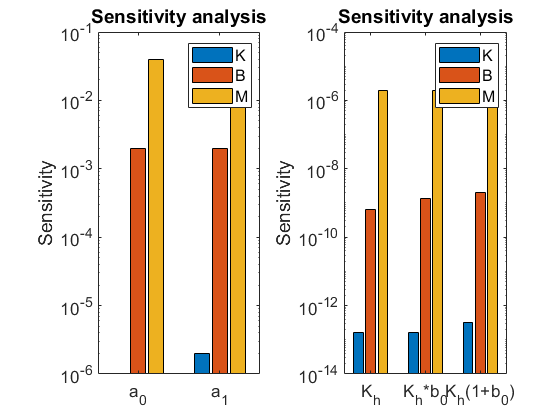

sens_a0 = double(subs(jacobian(a0,[Ks,Bs,Ms]),[Ks,Bs,Ms],[Kv,Bv,Mv]));
sens_a1 = double(subs(jacobian(a1,[Ks,Bs,Ms]),[Ks,Bs,Ms],[Kv,Bv,Mv]));
sens_Kh = double(subs(jacobian(Kh,[Ks,Bs,Ms]),[Ks,Bs,Ms],[Kv,Bv,Mv]));
sens_Khb0 = double(subs(jacobian(Kh*b0,[Ks,Bs,Ms]),[Ks,Bs,Ms],[Kv,Bv,Mv]));
sens_b = double(subs(jacobian(Kh*(1+b0),[Ks,Bs,Ms]),[Ks,Bs,Ms],[Kv,Bv,Mv]));
figure('DefaultAxesFontSize',14)
subplot(1,2,1)
bar(abs([sens_a0;sens_a1]))
set(gca,'YScale','log')
set(gca,'xticklabel',{'a_0';'a_1'})
title('Sensitivity analysis')
legend('K', 'B', 'M')
ylabel('Sensitivity')
subplot(1,2,2)
bar(abs([sens_Kh;sens_Khb0;sens_b]))
set(gca,'YScale','log')
set(gca,'xticklabel',{'K_h';'K_h*b_0';'K_h(1+b_0)'})
title('Sensitivity analysis')
legend('K', 'B', 'M')
ylabel('Sensitivity')

This local sensitity analysis reveals that the parameters $b_0 \;\textrm{and}\;K_h$ barely depends on the stifness parameter $K$. As shown before, $a_0 \;$ do not depends on $K$, and finaly $a_{1\;}$has a relatively low dependency on the stifness compared to both the mass and the damping. We can observe 3 orders of difference (${10}^3$) between the sensitivity of $a_{1\;}$to $K$and $B$. From the inverse point of view, it means that knowing the coefficients, it will be difficult to estimate the stifness.

## IV Identification

The parameters $a_1 ,a_0 ,b_0 ,K$ can be estimated using identification methodologies, with real dataset from human robot physical interactions.

### IV-a Data generation

#### 1) Real unperturbed data 

load 'data_2020_Nov_17/data_without_impacts_2020_11_17.mat' 't' 'thetas' 'forces_unf'
addpath('utils') % 
addpath('../../force_torque_sensor') % for force pre-processing

The data from the experiment is preprocessed to obtain a real shaped signal of the interaction force, that the robots applies on the environment $f_{r\to e\;}$.

%exp_nb = randi([1 15],1,1); % chose a random experimental dataset
exp_nb = 7;
t = t{exp_nb} - t{exp_nb}(1); % t0 = 0s
f_tmp = forces_filtering(forces_unf{exp_nb}', forces_unf{exp_nb}', thetas{exp_nb}', t); % from sensor base to robot base
%
[b,a] = butter(2,50/(1/(2*dt)),'low'); % BW 2nd order low pass filter (cutoff freq. 50 Hz)
f_tmp = -f_tmp(3,:)'; % fz conversion from f(e->r) to f(r->e), robot force on the environment
f = filtfilt(b,a,f_tmp); % zero phase digital filtering
clear forces_unf thetas f_tmp % clear unecessary data

#### 2) Simulation of the perturbations

This real input is then injected in a simulated system with known impedance parameters:

input_force.signals.values = f;
input_force.time = t;
% perturbation introduced in simulation
ext_signal = 1;
pert_mag = 10;
pert_space = ceil(2.8/dt); % samples
pert_duration = 0.030/dt;  % samples
% perturbation filter
xi = sqrt(2)/2;
w0 = 40*pi*1;
K_f = 3e3;
t_max = t(end);
out = sim('Impedance_env_simulation/KBM_sim',t_max);

The results from the simulation are collected:

fz = out.force.data;
z = out.position.data;
t = out.force.Time;
% get the rising edges indexes of the perturbations
pert_idx = find(diff(out.perturbations.data) > 0)';
pert_val = pert_mag.*ones(size(pert_idx));

#### 3) Virtual trajectories estimation

The data is then processed to extract the differential force and position trajectories between the virtual and the actual trajectories:

% PARAMETERS
idx_wndw_virt_traj   = ceil(0.200/dt); % 200ms (position)
idx_wndw_virt_f_traj = ceil(0.065/dt); % 65ms  (force) 
idx_wndw_imp_eval    = ceil(0.200/dt); % 200ms       
idx_delay            = ceil(0.000/dt); % 0ms
idx_window = max(idx_wndw_imp_eval, idx_wndw_virt_traj);
nb_param = 3; % K B M

% DATA PRE-PROCESSING
delta_z = DIFF_TRAJECT(idx_window, idx_wndw_virt_traj, z, t, pert_idx, pert_val, idx_delay);
delta_fz = DIFF_TRAJECT(idx_window, idx_wndw_virt_f_traj, fz, t, pert_idx, pert_val, idx_delay);
delta_fz_sine = DIFF_TRAJECT(idx_window, 100, fz, t, pert_idx, pert_val, idx_delay);

delta_z.computeDiffTraject('VirtTrajMethod', 'spline');
delta_fz.computeDiffTraject('VirtTrajMethod', 'filterPlus'); % this step might take few seconds
delta_fz_sine.computeDiffTraject('VirtTrajMethod', 'sineOptM', ...
    'OptSolverName', 'lsqnonlin', 'OptNbSine', 3, 'OptlinearComp', 0); % this step might take few seconds
delta_z.computeDerivatives();

#### 4) Evaluation of the virtual trajectories

The produced methodology can be compared to the actual - *simulated -* virtual trajectories:

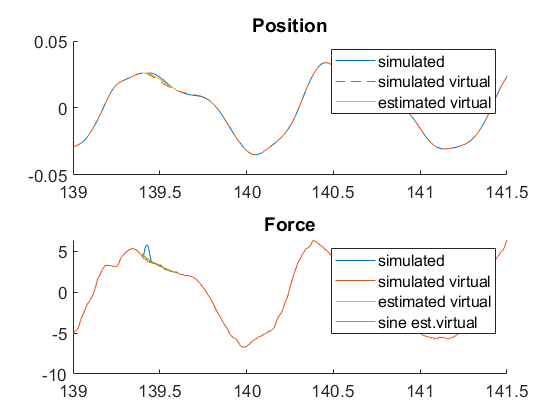

% real virtual trajectories
fz0 = out.virt_force.data;
z0 = out.virt_position.data;
%
figure('DefaultAxesFontSize',14)
subplot(2,1,1)
title('Position')
hold on
plot(t,z)
plot(t,z0, '--')
plot(delta_z.t_traject, delta_z.virt_traject, 'Color', [0.9290, 0.6940, 0.1250])
xlim([139 141.5])
legend('simulated', 'simulated virtual', 'estimated virtual')
subplot(2,1,2)
title('Force')
hold on
p1 = plot(t,fz);
p2 = plot(t,fz0);
p3 = plot(delta_fz.t_traject, delta_fz.virt_traject, 'Color', [0.9290, 0.6940, 0.1250]);
p4 = plot(delta_fz_sine.t_traject, delta_fz_sine.virt_traject, 'Color', [0.4660, 0.6740, 0.1880]);
xlim([139 141.5])
legend show
legend([p1,p2,p3(1),p4(1)], {'simulated', 'simulated virtual', 'estimated virtual', 'sine est.virtual'})

% Actual simulated virtual trajectories 
delta_z_sim = copyObj(delta_z);
delta_fz_sim = copyObj(delta_fz);
delay_wdw = delta_z.delay;
estim_wdw = delta_z.estim_window;
for i = 1:delta_z_sim.nb_traject
    pert_interval = delta_z_sim.pert_ind(i)+(-2:estim_wdw+1)+delay_wdw;
    delta_z_sim.virt_traject(:,i) = z0(pert_interval);
    delta_fz_sim.virt_traject(:,i) = fz0(pert_interval);
end
delta_z_sim.computeDiffTraject('VirtTrajMethod', 'manual');
delta_fz_sim.computeDiffTraject('VirtTrajMethod', 'manual');
% The result should be the same in this ideal scenario

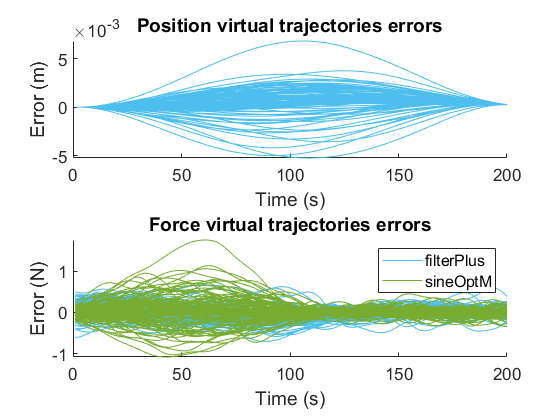

% 
figure('DefaultAxesFontSize',14)
subplot(2,1,1)
hold on
plot(delta_z.virt_traject-delta_z_sim.virt_traject, 'Color', [0.3010, 0.7450, 0.9330, 0.4])
title('Position virtual trajectories errors')
xlabel('Time (s)')
ylabel('Error (m)')
xlim([0, idx_wndw_imp_eval])
subplot(2,1,2)
hold on
p1 = plot(delta_fz.virt_traject-delta_fz_sim.virt_traject, 'Color', [0.3010, 0.7450, 0.9330, 0.4]);
p2 = plot(delta_fz_sine.virt_traject-delta_fz_sim.virt_traject, 'Color', [0.4660, 0.6740, 0.1880, 0.4]);
title('Force virtual trajectories errors')
xlabel('Time (s)')
ylabel('Error (N)')
xlim([0, idx_wndw_imp_eval])
legend([p1(1),p2(1)], {'filterPlus', 'sineOptM'})

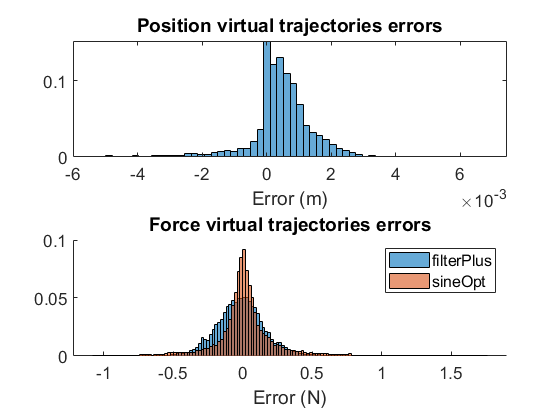

% Errors histograms
figure('DefaultAxesFontSize',14)
subplot(2,1,1)
histogram(delta_z.virt_traject-delta_z_sim.virt_traject, 60, 'Normalization', 'probability')
title('Position virtual trajectories errors')
xlabel('Error (m)')
subplot(2,1,2)
hold on
histogram(delta_fz.virt_traject-delta_fz_sim.virt_traject,...
    'Normalization', 'probability','BinWidth',0.02)
histogram(delta_fz_sine.virt_traject-delta_fz_sim.virt_traject, ...
    'Normalization', 'probability','BinWidth',0.02)
title('Force virtual trajectories errors')
legend('filterPlus', 'sineOpt')
xlabel('Error (N)')

### IV-b Discrete time identification algorithms

 We define two polynomials $A_k$ and $B_k \;$such as: %% TODO rewrite this expression in accordance to the knew representation using the transfer function


$$y\left(t\right)+a_1 y\left(t-1\right)+a_0 y\left(t-2\right)=b_1 \;u\left(t\right)+b_0 \;u\left(t-1\right)+e\left(t\right)$$



$$A_k \left(q\right)y\left(t\right)=B_k \left(q\right)u\left(t\right)+e\left(t\right),$$


with $q$ the delay operator.

% Data formating for identification
for i = delta_z.nb_traject:-1:1 
%     data{i} = iddata(delta_z.diff_traject(:,i) - mean(delta_z.diff_traject(:,i)), ...
%         delta_fz.diff_traject(:,i) - mean(delta_fz.diff_traject(:,i)),dt);
    data{i} = iddata(delta_z.diff_traject(:,i) - delta_z.diff_traject(1,i), ...
        delta_fz.diff_traject(:,i) - delta_fz.diff_traject(1,i),dt);
    %data{i} = iddata(delta_z.diff_traject(:,i), delta_fz.diff_traject(:,i), dt);
    data{i}.TimeUnit = 's';
    data{i}.InputUnit = 'N';
    data{i}.OutputUnit = 'm'; 
    % Sine optimization data
    data_sine{i} = iddata(delta_z.diff_traject(:,i) - delta_z.diff_traject(1,i), ...
        delta_fz_sine.diff_traject(:,i) - delta_fz_sine.diff_traject(1,i),dt);
    data_sine{i}.TimeUnit = 's';
    data_sine{i}.InputUnit = 'N';
    data_sine{i}.OutputUnit = 'm'; 
end
% ideal data
% data_sim = iddata(delta_z_sim.diff_traject(:,1)-mean(delta_z_sim.diff_traject(:,1)),...
%     delta_fz_sim.diff_traject(:,1)-mean(delta_fz_sim.diff_traject(:,1)),dt);
data_sim = iddata(delta_z_sim.diff_traject(:,1)-delta_z_sim.diff_traject(1,1),...
    delta_fz_sim.diff_traject(:,1)-delta_fz_sim.diff_traject(1,1),dt);
data_sim.TimeUnit = 's';
data_sim.InputUnit = 'N';
data_sim.OutputUnit = 'm';

The ARX identification method can now be used, since we know the order of the polynomials $A_k$ and $B_k$:

na = length(a_coef)-1; % order of Ak
nb = length(b_coef)-1; % order of Bk
nk = 0; % delay in Bk
opts = arxOptions('InitialCondition','zero');
for i = delta_z.nb_traject:-1:1 
    arx_id{i} = arx(data{i},[na nb+1 nk], opts);
    arx_id{i}.Name = 'Arx ID';
    arx_sine_id{i} = arx(data_sine{i},[na nb+1 nk], opts);
    arx_sine_id{i}.Name = 'Arx ID sine traj';
end
arx_id_sim = arx(data_sim,[na nb+1 nk], opts);
arx_id_sim.Name = 'Arx ID with ideal data';

The quality of the identification can be estimated... to be continued...

%
% for i = delta_z.nb_traject:-1:1 
%     pem_id{i} = pem(data{i},arx_id{i});
%     pem_id{i}.Name = 'Pem ID';
% end

A random estimation is picked to compare the quality of the estimation:

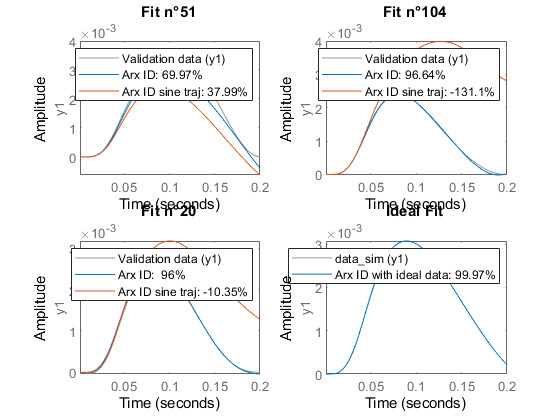

rand_idx = randi([1 delta_z.nb_traject],3,1);
figure('DefaultAxesFontSize',12)
opts = compareOptions('InitialCondition', 'z');
for i = 1:3
    subplot(2,2,i)
    compare(data{rand_idx(i)},arx_id{rand_idx(i)}, arx_sine_id{rand_idx(i)}, Inf, opts);
    title("Fit n°" + string(rand_idx(i)))
end
%figure('DefaultAxesFontSize',14)
subplot(2,2,4)
compare(data_sim,arx_id_sim, Inf, opts);
title("Ideal Fit")

A wider overview is then displayed:

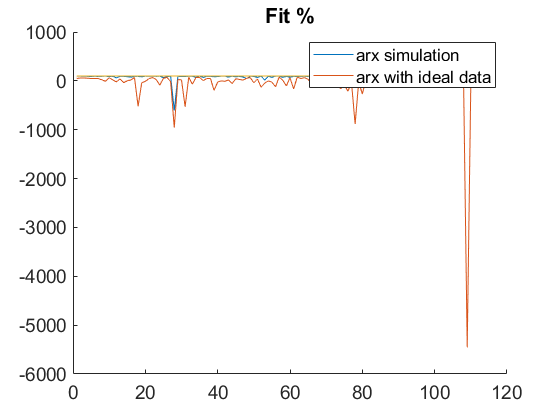

for i = delta_z.nb_traject:-1:1 
    % Report fit default horizon is set to 1, how do we change it ?
    %arx_id_fit1(i) = arx_id{i}.Report.Fit.FitPercent; 
    [~,arx_id_fit(i),x0(i)] = compare(data{i},arx_id{i}, Inf, opts);
    [~,arx_sine_id_fit(i),x0_sine(i)] = compare(data{i},arx_sine_id{i}, Inf, opts);
    %[~,arx_pred_fit(i),~] = compare(data{i},arx_id{i}, 1);
end
[~,arx_id_sim_fit,x0_sim] = compare(data_sim,arx_id_sim, Inf, opts);
figure('DefaultAxesFontSize',14)
hold on
plot(arx_id_fit)
plot(arx_sine_id_fit)
%plot(arx_pred_fit)
plot([1, delta_z.nb_traject], [arx_id_sim_fit, arx_id_sim_fit])
title('Fit %')
legend('arx simulation', 'arx with ideal data')

%legend('arx simulation', 'arx prediction','arx with ideal data')

To see the variations in the identified model, we plot the bode diagram for every identification:

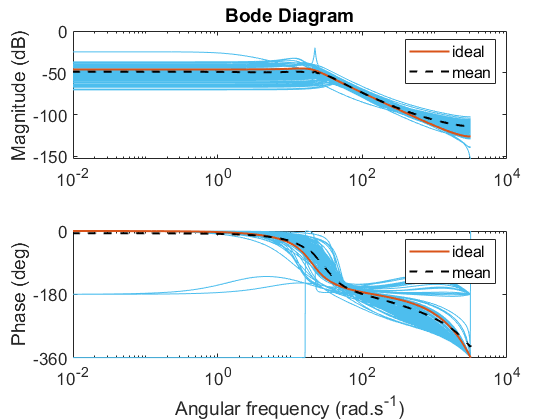

% Bode plotting takes too much time
% figure('DefaultAxesFontSize',14)
% hold on
% for i = 1:length(arx_id)
%     bode(arx_id{i}.B,arx_id{i}.A, ':');
% end
% bode(arx_id_sim.B,arx_id_sim.A,'r');
f = logspace(-2,log10(pi/dt),1e3);
for i = 1:length(arx_id)
    [mag(:,i), pha(:,i)] = bode(tf(arx_id{i}.B,arx_id{i}.A,dt),f);
end
 [mag_sim, pha_sim] = bode(tf(arx_id_sim.B,arx_id_sim.A,dt),f);
% Manual bode plot
figure('DefaultAxesFontSize',14)
for i = 1:length(arx_id)
    subplot(2,1,1)
    semilogx(f, 20*log10(abs(mag(:,i))), 'Color', [0.3010, 0.7450, 0.9330, 0.4]);
    hold on
    subplot(2,1,2)
    semilogx(f, mod(pha(:,i),-360), 'Color', [0.3010, 0.7450, 0.9330, 0.4]);
    hold on
end
subplot(2,1,1)
title('Bode Diagram')
ylabel('Magnitude (dB)')
p1 = semilogx(f, 20*log10(abs(mag_sim(:))), 'Color', [0.8500, 0.3250, 0.0980], ...
    'LineWidth', 1.5);
p2 = semilogx(f, 20*log10(abs(mean(mag,2))), 'k--','LineWidth', 1.5);
legend([p1 p2],'ideal','mean')
subplot(2,1,2)
ylabel('Phase (deg)')
p1 = semilogx(f, mod(pha_sim(:),-360), 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
p2 = semilogx(f, mean(mod(pha,-360),2), 'k--','LineWidth', 1.5);
ylim([-361 inf])
yticks([-360, -180, 0, 180])
legend([p1 p2],'ideal','mean')
xlabel('Angular frequency (rad.s^{-1})')

### IV-c Optimization 

To improve the estimation of the ARX parameter, an optimization can be conducted. The initial parameters can be choosen as those returned previoulsy. Therefore, a non linear layer is added to improve the identification of the coefficients.

% Ideal case scenario
u_opt = data_sim.InputData;
y_opt = data_sim.OutputData;
param_init(1:3) = arx_id_sim.A;
param_init(4:5) = arx_id_sim.B;
options = optimset('fminunc');
options = optimset(options,'MaxFunEvals',2000,'Display', 'off');
[p_argmin, coeffs, exit_flag, info] = fminunc(@(par)arxModelEval(par, u_opt, y_opt),...
    param_init, options); 
% 
for i = length(arx_id):-1:1
    u_opt = data{i}.InputData;
    y_opt = data{i}.OutputData;
    param_init(1:3) = arx_id{i}.A;
    param_init(4:5) = arx_id{i}.B;   
    [p_argmin, coeffs, exit_flag, info] = fminunc(@(par)arxModelEval(par, u_opt, y_opt),...
    param_init, options); 
    opt_id(i).A(1:3) = p_argmin(1:3);
    opt_id(i).B(1:2) = p_argmin(4:5);
    opt_id(i).exit_flag = exit_flag;
    opt_id(i).info = info;
end

### IV-d Impedance parameters identification

#### 1) Numerical methodology

Once the coefficients of $A_k$ and $B_k$ are identified, the impedance parameters can be deduced thanks to the relations detailed in the *Discretization* paragraph for every identification conducted for each perturbation:

$a_1 =\frac{{a_1 }^{\prime } }{{a_2 }^{\prime } }$ , $a_0 =\frac{{a_0 }^{\prime } }{{a_2 }^{\prime } }$ , $K_h \left(1+b_0 \right)=\frac{{b_1 }^{\prime } +{b_0 }^{\prime } }{{a_2 }^{\prime } }$

% K D M identification
for i = 1:length(arx_id)
    % declare the equations system
    eq.A(1) = a1 - arx_id{i}.A(2)/arx_id{i}.A(1) == 0;
    eq.A(2) = a0 - arx_id{i}.A(3)/arx_id{i}.A(1) == 0;
    eq.B(1) = Kh*(b0 + 1) - (arx_id{i}.B(1) + arx_id{i}.B(2))/arx_id{i}.A(1) == 0;
    imp_param_id(i) = vpasolve([eq.A(1),eq.A(2),eq.B(1)],[Ks;Bs;Ms]);
    if i == 1
        warning('off','all'); % to avoid  spam warnings in the loop
    end
end
warning('on','all')

Same process on the ideal case scenario

eq.A(1) = a1 - arx_id_sim.A(2)/arx_id_sim.A(1) == 0;
eq.A(2) = a0 - arx_id_sim.A(3)/arx_id_sim.A(1) == 0;
eq.B(1) = Kh - arx_id_sim.B(1)/arx_id_sim.A(1) == 0;
eq.B(2) = b0 - arx_id_sim.B(2)/arx_id_sim.B(1) == 0;
eq.B(3) = Kh*b0 - arx_id_sim.B(2)/arx_id_sim.A(1) == 0;
eq.B(4) = Kh*(b0 + 1) - (arx_id_sim.B(1) + arx_id_sim.B(2))/arx_id_sim.A(1) == 0;
imp_param_id_sim = vpasolve([eq.A(1),eq.A(2),eq.B(4)],[Ks;Bs;Ms]);
% implementation of the live script in the class IMPEDANCE_DATA
% impedance = IMPEDANCE_DATA(3, length(arx_id), idx_wndw_imp_eval);
% impedance.init_phi(delta_z.diff_traject(1:idx_wndw_imp_eval,:), ...
%         delta_z.d_diff_traject(1:idx_wndw_imp_eval,:), ... % speed
%         delta_z.dd_diff_traject(1:idx_wndw_imp_eval,:)); % acc
% impedance.init_y(delta_fz.diff_traject(1:idx_wndw_imp_eval,:));
% impedance.arx();
% expected arx param
double(subs(a1, [Ks, Bs, Ms], [Kv, Bv, Mv]))

ans = -1.9798

double(subs(a0, [Ks, Bs, Ms], [Kv, Bv, Mv]))

ans = 0.9802

double(subs(Kh*(b0+1), [Ks, Bs, Ms], [Kv, Bv, Mv]))

ans = 1.9801e-06

#### 2) Analytical methodology

We can also use the eigenvalues of $A_d$, to express the impedance parameters in terms of arx discrete coefficients. Since the poles of $H_d$ are equal to the eigenvalues of ${\mathit{\mathbf{A}}}_d$, we have the following equality:

 $\begin{array}{l}
\alpha_1 =\frac{-a_1 +{\left(a_1^2 -4\;a_0 \right)}^{\frac{1}{2}} }{2}=e^{\frac{-B+{\left(B^2 -4\textrm{MK}\right)}^{\frac{1}{2}} }{2M}\;T} \\
\alpha_2 =\frac{-a_1 -{\left(a_1^2 -4\;a_0 \right)}^{\frac{1}{2}} }{2}=e^{\frac{-B-{\left(B^2 -4\textrm{MK}\right)}^{\frac{1}{2}} }{2M}\;T} 
\end{array}$    (iv-d-2-1)

The equations (iv-d-2-1) can be sum up after using the natural logarithm to find a relation between $B$ and $M$ :


$$\ln \left(\alpha_1 \right)+\ln \left(\alpha_2 \right)=-\frac{B}{M}T$$



$$\Rightarrow$$

$$B=-\ln \left(\alpha_1 \alpha_2 \right)\frac{M}{T}=-\ln \left(a_0 \right)\frac{M}{T}$$


Finally, the expression of $B$ and $K$can be injected in one of the equations (iv-d-2-1) to solve $M$:


$$M=-\frac{{KT}^2 }{{\left(\mathrm{ln}\left(\alpha_1 \right)-\frac{\mathrm{ln}\left(a_0 \right)}{2}\right)}^2 -{\left(\frac{\mathrm{ln}\left(a_0 \right)}{2}\right)}^2 }=\frac{-{KT}^2 }{\mathrm{ln}\left(\alpha_1 \right)\left(\mathrm{ln}\left(\alpha_1 \right)-\mathrm{ln}\left(a_0 \right)\right)}$$


#### DC gain

Then if we apply the final value theorem, we can determine the gain of the transfer function and underline a final relation:


$$\lim_{t\to +\infty } {\;f}_e \left(t\right)=\lim_{s\to 0} {\;\textrm{sF}}_e \left(s\right)=\lim_{z\to 1} {\;\left(z-1\right)F}_e \left(z\right)$$


Considering a unitary step input $X_e$: 


$$\lim_{s\to 0} {\;\textrm{sF}}_e \left(s\right)=\lim_{s\to 0} \;s\;\left({\textrm{Ms}}^2 +\textrm{Bs}+K\right)X_e \left(p\right)=K$$



$$\lim_{z\to 1} {\;\left(z-1\right)F}_e \left(z\right)=\lim_{z\to 1} \frac{\left(z-1\right)}{K_H }\frac{z^2 +a_1 z+a_0 }{z+b_0 }X_e \left(z\right)=\frac{1+a_1 +a_0 }{K_H \left(1+b_0 \right)}$$



$$\Rightarrow K=\frac{1+a_1 +a_0 }{K_H \left(1+b_0 \right)}$$


for i = length(arx_id):-1:1
    K_id(i) = (arx_id{i}.A(1) + arx_id{i}.A(2) + arx_id{i}.A(3))/...
        (arx_id{i}.B(1) + arx_id{i}.B(2));
    % if arx_id{i}.A(1) ~= 1 this will bring a wrong result
    alpha1 = (-arx_id{i}.A(2)+sqrt(arx_id{i}.A(2)^2-4*arx_id{i}.A(3)))/2;
    M_id(i) = real(-K_id(i)*dt^2/(log(alpha1)*(log(alpha1)-log(arx_id{i}.A(3)))));
    B_id(i) = -M_id(i)/dt*log(arx_id{i}.A(3)/arx_id{i}.A(1));
    % for sine trajectory
    K_sine_id(i) = (arx_sine_id{i}.A(1) + arx_sine_id{i}.A(2) + arx_sine_id{i}.A(3))/...
        (arx_sine_id{i}.B(1) + arx_sine_id{i}.B(2));
    alpha1s = (-arx_sine_id{i}.A(2)+sqrt(arx_sine_id{i}.A(2)^2-4*arx_sine_id{i}.A(3)))/2;
    M_sine_id(i) = real(-K_sine_id(i)*dt^2/(log(alpha1s)*(log(alpha1s)-log(arx_sine_id{i}.A(3)))));
    B_sine_id(i) = -M_sine_id(i)/dt*log(arx_sine_id{i}.A(3)/arx_sine_id{i}.A(1));
end
% Ideal case scenario
K_id_sim = (arx_id_sim.A(1) + arx_id_sim.A(2) + arx_id_sim.A(3))/...
    (arx_id_sim.B(1) + arx_id_sim.B(2));
% if arx_id{i}.A(1) ~= 1 this will bring a wrong result
alpha1 = (-arx_id_sim.A(2)+sqrt(arx_id_sim.A(2)^2-4*arx_id_sim.A(3)))/2;
M_id_sim = real(-K_id_sim*dt^2/(log(alpha1)*(log(alpha1)-log(arx_id_sim.A(3)))));
B_id_sim = -M_id_sim/dt*log(arx_id_sim.A(3)/arx_id_sim.A(1));

% Same identification for the optimized coefficients
for i = length(arx_id):-1:1
    K_opt(i) = (opt_id(i).A(1) + opt_id(i).A(2) + opt_id(i).A(3))/...
        (opt_id(i).B(1) + opt_id(i).B(2));
    % if arx_id{i}.A(1) ~= 1 this will bring a wrong result
    alpha1 = (-opt_id(i).A(2)+sqrt(opt_id(i).A(2)^2-4*opt_id(i).A(3)))/2;
    M_opt(i) = real(-K_opt(i)*dt^2/(log(alpha1)*(log(alpha1)-log(opt_id(i).A(3)))));
    B_opt(i) = -M_opt(i)/dt*log(opt_id(i).A(3)/opt_id(i).A(1));
end
% Ideal case scenario
K_opt_id = (p_argmin(1) + p_argmin(2) + p_argmin(3))/...
    (p_argmin(4) + p_argmin(5));
% if arx_id{i}.A(1) ~= 1 this will bring a wrong result
alpha1 = (-p_argmin(2)+sqrt(p_argmin(2)^2-4*p_argmin(3)))/2;
M_opt_id = real(-K_opt_id*dt^2/(log(alpha1)*(log(alpha1)-log(p_argmin(3)))));
B_opt_id = -M_opt_id/dt*log(p_argmin(3)/p_argmin(1));

#### Natural angular frequency

Another possible solution to evaluate $K$, is to use the natural frequency $\omega_n$. Indeed, in the continuous model, it is straight forward to note that $\omega_n =\sqrt{\frac{K}{M}}$. Then in the discrete model, the natural frequency can be evaluated with the ARX coefficients, with $\alpha_i$ being the poles of the system $\omega_n =\left|\frac{\ln \left(\alpha_i \right)}{T}\right|$.


$$K={\left|\frac{\ln \left(\alpha_i \right)}{T}\right|}^2 M$$


This methods requires the system to have a oscillatory behaviour, meaning that $\alpha_i$ are complex numbers with non nul imaginary part, and $M$ must be known (which is the case usualy).

(abs(log(alpha1))/dt)^2*M_id_sim, (abs(log(alpha1s))/dt)^2*M_id_sim

ans = 348.1424

ans = 261.9225

## VI Results

### VI-a Parameters validation

The identified parameters are:

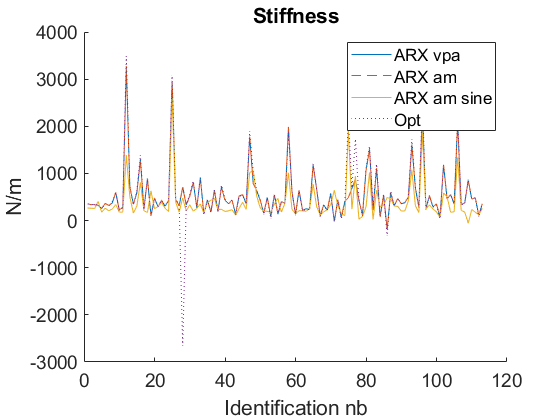

figure('DefaultAxesFontSize',14)
title('Stiffness')
hold on
plot([imp_param_id(:).Ks])
plot(K_id, '--')
plot(K_sine_id)
% plot(impedance.xi(1,:),  ':')
plot(K_opt,  ':')
legend('ARX vpa', 'ARX am', 'ARX am sine', 'Opt')
xlabel('Identification nb')
ylabel('N/m')

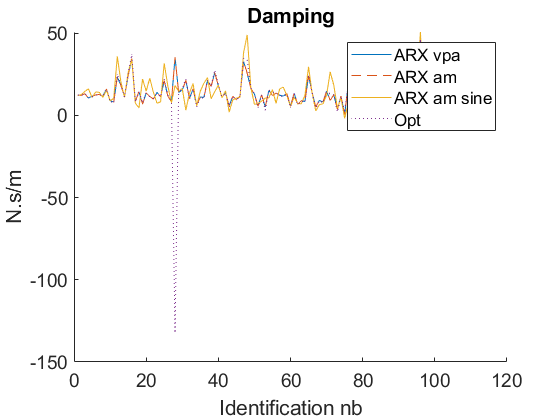

figure('DefaultAxesFontSize',14)
title('Damping')
hold on
plot([imp_param_id(:).Bs])
plot(B_id, '--')
plot(B_sine_id)
% plot(impedance.xi(2,:),  ':')
plot(B_opt,  ':')
legend('ARX vpa', 'ARX am', 'ARX am sine', 'Opt')
xlabel('Identification nb')
ylabel('N.s/m')

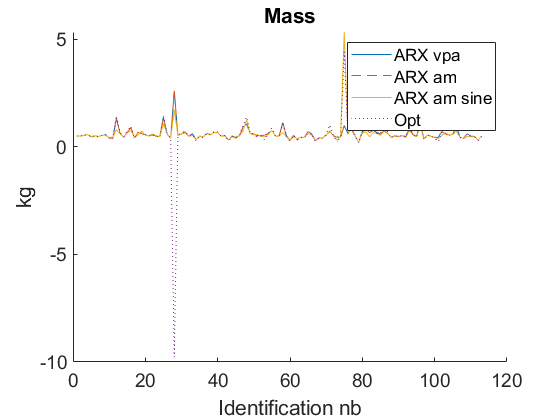

figure('DefaultAxesFontSize',14)
title('Mass')
hold on
plot([imp_param_id(:).Ms])
plot(M_id, '--')
plot(M_sine_id)
% plot(impedance.xi(3,:),  ':')
plot(M_opt,  ':')
legend('ARX vpa', 'ARX am', 'ARX am sine', 'Opt')
xlabel('Identification nb')
ylabel('kg')

If we take away the outiliers,and compute the average and the standard deviation, we have the following results:

mean(rmoutliers(double([imp_param_id(:).Ks]))), mean(rmoutliers(K_id)), mean(rmoutliers(K_sine_id)), mean(rmoutliers(K_opt))

ans = 409.7304

ans = 409.7304

ans = 258.1848

ans = 395.1735

mean(rmoutliers(double([imp_param_id(:).Bs]))), mean(rmoutliers(B_id)), mean(rmoutliers(B_sine_id)), mean(rmoutliers(B_opt))

ans = 12.8675

ans = 12.8675

ans = 12.5486

ans = 12.8831

mean(rmoutliers(double([imp_param_id(:).Ms]))), mean(rmoutliers(M_id)), mean(rmoutliers(M_sine_id)), mean(rmoutliers(M_opt))

ans = 0.5407

ans = 0.5407

ans = 0.5227

ans = 0.5303

In the ideal case scenario, where the virtual trajectories are known, the methodology gives the following relative error to the 3 impedance parameters:

abs(double(imp_param_id_sim.Ks)-Kv)/Kv*100, abs((K_id_sim)-Kv)/Kv*100, abs((K_opt_id)-Kv)/Kv*100

ans = 0.0306

ans = 0.0306

ans = 76.8260

abs(double(imp_param_id_sim.Bs)-Bv)/Bv*100, abs((B_id_sim)-Bv)/Bv*100, abs((B_opt_id)-Bv)/Bv*100

ans = 0.0053

ans = 0.0053

ans = 23.3499

abs(double(imp_param_id_sim.Ms)-Mv)/Mv*100, abs((M_id_sim)-Mv)/Mv*100, abs((M_opt_id)-Mv)/Mv*100

ans = 0.0529

ans = 0.0529

ans = 1.6363

### VI-b Reconstruction

#### 1) Position reconstruction (causal)

Once the impedance parameters are identified, it is possible to reconstruct the position trajectory due to the force perturbation. If the parameters were well identified from the ARX coefficient (IV-d), the results should be the same as the reconstruction done with the ARX coefficient (IV-b).

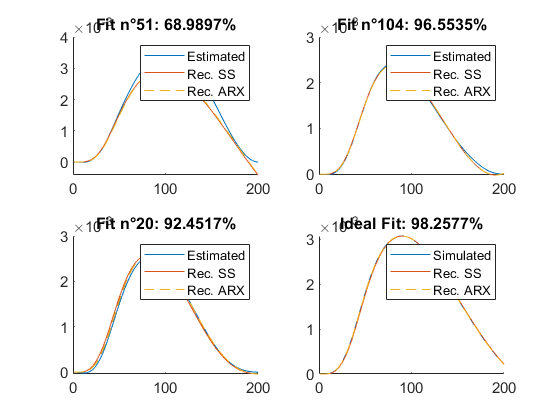

for i = length(arx_id):-1:1
    % identified system
    Adssi = double(subs(Ad, [Ks, Bs, Ms], [K_id(i), B_id(i), M_id(i)]));
    Bdssi = real(double(subs(Bd, [Ks, Bs, Ms], [K_id(i), B_id(i), M_id(i)])));
    KBM_dssi{i} = ss(Adssi,Bdssi,C,0,dt);
    % reconstruction simulation with identified parameters
    %[~,~,ic(:,i)] = compare(data{i}, KBM_ssi);
    ic(1,i) = data{i}.OutputData(1);
    ic(2,i) = delta_z.d_diff_traject(1,i);
    rec_pos(:,i) = lsim(KBM_dssi{i}, data{i}.InputData, dt*(0:199), ic(:,i));
    opts = simOptions('InitialCondition', x0(i));
    rec_pos_arx{i} = sim(arx_id{i}, data{i}, opts);
    opts = simOptions('InitialCondition', x0_sine(i));
    rec_pos_arx_sine{i} = sim(arx_sine_id{i}, data_sine{i}, opts);
end
% simulated reconstruction with known parameters
%[~,~,ic_sim] = compare(data{i}, KBM_ssi);
ic_sim(1) = data_sim.OutputData(1);
ic_sim(2) = delta_z_sim.d_diff_traject(1,i);
rec_pos_id = lsim(KBM_dss, data_sim.InputData, dt*(0:199), ic_sim);
opts =  simOptions('InitialCondition', x0_sim);
rec_pos_arx_id = sim(arx_id_sim, data_sim, opts);
% 
figure('DefaultAxesFontSize',12)
for i = 1:3
    subplot(2,2,i)
    hold on
    plot(data{rand_idx(i)}.OutputData);
    plot(rec_pos(:,rand_idx(i)));
    plot(rec_pos_arx{rand_idx(i)}.OutputData,'--');
    plot(rec_pos_arx_sine{rand_idx(i)}.OutputData);
    legend('Estimated', 'Rec. SS', 'Rec. ARX', 'Rec. ARX sine')
    nrmse_i = norm(rec_pos(:,rand_idx(i)) - data{rand_idx(i)}.OutputData)/...
        norm(mean(data{rand_idx(i)}.OutputData) - data{rand_idx(i)}.OutputData);
    title("Fit n°" + string(rand_idx(i)) + ": " + string(100*(1-nrmse_i)) + "%")
end
subplot(2,2,4)
hold on
plot(data_sim.OutputData);
plot(rec_pos_id);
plot(rec_pos_arx_id.OutputData, '--');
legend('Simulated', 'Rec. SS', 'Rec. ARX')
nrmse_i = norm(data_sim.OutputData - rec_pos_id)/...
    norm(mean(data_sim.OutputData) - data_sim.OutputData);
title("Ideal Fit: " + string(100*(1-nrmse_i)) + "%")

#### 2) Force reconstruction (non causal)

In this non causal case, the inputs are the position, and its derivatives (velocity and acceleration).

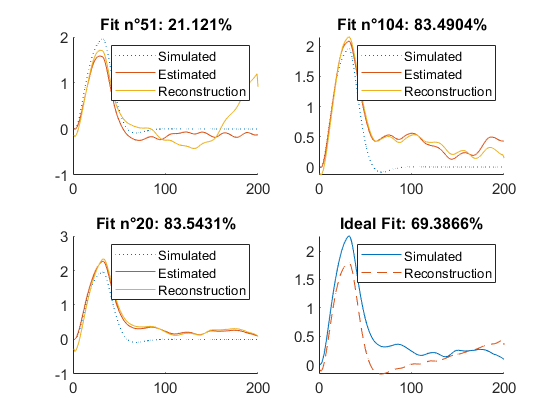

for i = length(arx_id):-1:1
    % identified system
    xi = [K_id(i); B_id(i); M_id(i)];
    phi = [data{i}.OutputData, delta_z.d_diff_traject(:,i), delta_z.dd_diff_traject(:,i)];
    % reconstruction simulation with identified parameters
    rec_for(:,i) = phi*xi;
end
xi_id = [K_id_sim; B_id_sim; M_id_sim];
phi_id = [data_sim.OutputData, delta_z_sim.d_diff_traject(:,1), delta_z_sim.dd_diff_traject(:,1)];
rec_for_id = phi_id*xi_id;
figure('DefaultAxesFontSize',12)
for i = 1:3
    subplot(2,2,i)
    hold on
    plot(data_sim.InputData, ':');
    plot(data{rand_idx(i)}.InputData);
    plot(rec_for(:,rand_idx(i)));
    legend('Simulated', 'Estimated', 'Reconstruction')
    nrmse_i = norm(rec_for(:,rand_idx(i)) - data{rand_idx(i)}.InputData)/...
        norm(mean(data{rand_idx(i)}.InputData) - data{rand_idx(i)}.InputData);
    title("Fit n°" + string(rand_idx(i)) + ": " + string(100*(1-nrmse_i)) + "%")
end
subplot(2,2,4)
hold on
plot(data{rand_idx(i)}.InputData);
plot(rec_for_id, '--');
legend('Simulated', 'Reconstruction')
nrmse_i = norm(data_sim.InputData - rec_for_id)/...
    norm(mean(data_sim.InputData) - data_sim.InputData);
title("Ideal Fit: " + string(100*(1-nrmse_i)) + "%")

We can see that the force reconstruction is less accurate since it relies on numerical derivatives of the position for both the velocity and the acceleration.

## Annexes

### Functions

Functions that allows deep copy of objects from classes with "*handle*" inheritance. Otherwise a = b, does not create a copy of b, but rather a pointor to b, meaning that any modification on either a or b will also modify the other object.

function b = copyObj(a)
   b = eval(class(a));  %create default object of the same class as a. one valid use of eval
   for p =  properties(a).'  %copy all public properties
      try   %may fail if property is read-only
         b.(p{1}) = a.(p{1});
      catch
         warning('failed to copy property: %s', p);
      end
   end
end

Evaluation function for the optimization of the ARX coefficients.

function score = arxModelEval(param, u, y)
    if length(u) ~= length(y)
        error('Input and output size muste be the same!')
    end
    A(1:3) = param(1:3);
    B(1:2) = param(4:5);
    y_hat = zeros(size(y));
    % initial conditions are considered nul
    for ii = 1:length(u)
        if ii == 1
            u_i(1) = u(ii);
            u_i(2) = 0;
            y_hat_i(1) = 0;
            y_hat_i(2) = 0;
        elseif ii == 2
            u_i(1) = u(ii);
            u_i(2) = u(ii-1);
            y_hat_i(1) = y_hat(ii-1);
            y_hat_i(2) = 0;
        else
            u_i(1) = u(ii);
            u_i(2) = u(ii-1);
            y_hat_i(1) = y_hat(ii-1);
            y_hat_i(2) = y_hat(ii-2);
        end
        y_hat(ii) = (B(1)*u_i(1) + B(2)*u_i(2) - A(2)*y_hat_i(1) - A(3)*y_hat_i(2))/A(1);
    end    
    score = sum((y_hat-y).^2);
end